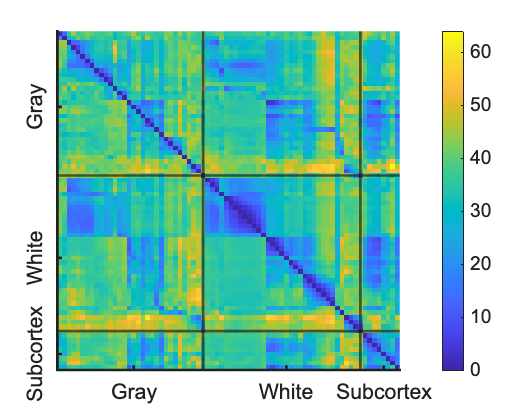

clc;clear;close all;
subG = {'sub-0001', 'sub-0002', 'sub-0003', 'sub-0004', 'sub-0005', ...
        'sub-0007', 'sub-0008', 'sub-0009', 'sub-0010', 'sub-0011', ...
        'sub-0012', 'sub-0013', 'sub-0014', 'sub-0015', 'sub-0016', ...
        'sub-0017', 'sub-0019', 'sub-0020', 'sub-0021', 'sub-0022', ...
        'sub-0023', 'sub-0028', 'sub-0029', 'sub-0031', 'sub-0033', ...
        'sub-0034', 'sub-0035', 'sub-0036', 'sub-0039', 'sub-0046', ...
        'sub-0047', 'sub-0050', 'sub-0052', 'sub-0054', 'sub-0062', ...
        'sub-0063', 'sub-0066', 'sub-0067', 'sub-0074', 'sub-0077', ...
        'sub-0087', 'sub-0089', 'sub-0092', 'sub-0093', 'sub-0094', ...
        'sub-0113', 'sub-0115'};
DistPath = 'step2_channelDistance';
elecPath = 'step1_AwakeSEEG_BPfiltering_Age16Up';
load(fullfile('step4_IEDtw_polyfit_TD6d0', 'IEDtw_meth-None_TD-6d0.mat'));
xfull = []; yfull = []; zfull = [];
nS = 2; subID = subG{nS};
load(fullfile(elecPath, subID, [subID, '_ROI-3mm_contactAnatomy.mat']));
IEDlabels = IEDtw(nS).label;
CWS = {};
for nChan = 1:length(IEDlabels)
    a = strcmp(IEDlabels{nChan}, contAnat.label);
    CWS{nChan} = contAnat.CWS{a==1};
end
a = ismember(CWS, 'Cortex');
cortexIdxMean = round(mean(find(a==1)));
cortexIdxMax = max(find(a==1));
a = ismember(CWS, 'White');
whiteIdxMean = round(mean(find(a==1)));
whiteIdxMax = max(find(a==1));
a = ismember(CWS, 'Subcortex');
subcortexIdxMean = round(mean(find(a==1)));
% ===== Visualization IED TW Delays Matrix =====
delay = IEDtw(nS).indirectTransferDelayMatrix;
figure('Units', 'centimeters', 'Position', [5, 5, 14, 11]);
imagesc(delay);
xline(cortexIdxMax, 'LineWidth', 2); 
yline(cortexIdxMax, 'LineWidth', 2);
xline(whiteIdxMax, 'LineWidth', 2); yline(whiteIdxMax, 'LineWidth', 2);
xticks([cortexIdxMean, whiteIdxMean, subcortexIdxMean]);
xticklabels({'Gray', 'White', 'Subcortex'});
yticks([cortexIdxMean, whiteIdxMean, subcortexIdxMean]);
yticklabels({'Gray', 'White', 'Subcortex'}); 
colorbar; colormap parula;
set(gca, 'box', 'off', 'FontName', 'Arial', ...
    'FontSize', 16, 'LineWidth', 2, 'YTickLabelRotation', 90);

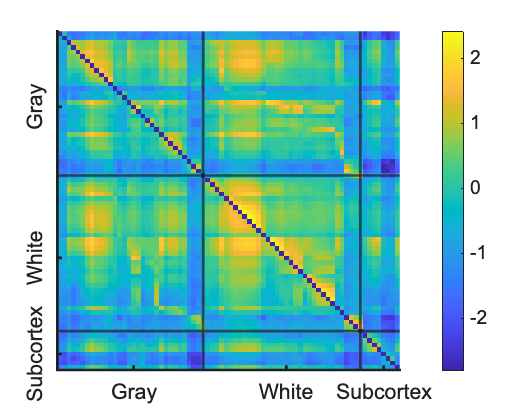

% ===== Visualization Transfer Rate Matrix =====
rate = log(IEDtw(nS).indirectTransferRateMatrix);
figure('Units', 'centimeters', 'Position', [5, 5, 14, 11]);
imagesc(rate);
xline(cortexIdxMax, 'LineWidth', 2);
yline(cortexIdxMax, 'LineWidth', 2);
xline(whiteIdxMax, 'LineWidth', 2);
yline(whiteIdxMax, 'LineWidth', 2);
xticks([cortexIdxMean, whiteIdxMean, subcortexIdxMean]);
yticks([cortexIdxMean, whiteIdxMean, subcortexIdxMean]);
xticklabels({'Gray', 'White', 'Subcortex'});
yticklabels({'Gray', 'White', 'Subcortex'}); 
colorbar; colormap parula;
set(gca, 'box', 'off', 'FontName', 'Arial', ...
    'FontSize', 16, 'LineWidth', 2, 'YTickLabelRotation', 90);

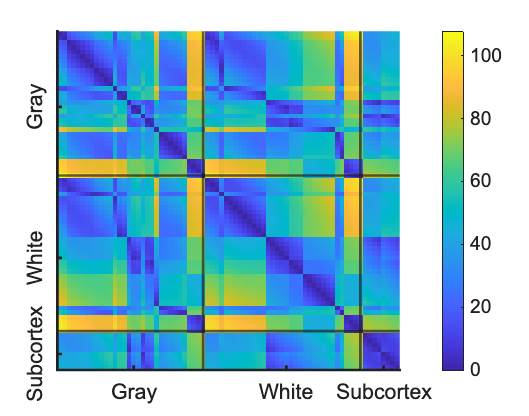

% Visualization Distance Matrix
load(fullfile(DistPath, [subID,'_EuclideabDistanceMatrix.mat']));
figure('Units', 'centimeters', 'Position', [5, 5, 14, 11]);
imagesc(DistanceWorld);
xline(cortexIdxMax, 'LineWidth', 2); yline(cortexIdxMax, 'LineWidth', 2);
xline(whiteIdxMax, 'LineWidth', 2); yline(whiteIdxMax, 'LineWidth', 2);
xticks([cortexIdxMean, whiteIdxMean, subcortexIdxMean]);
yticks([cortexIdxMean, whiteIdxMean, subcortexIdxMean]);
xticklabels({'Gray', 'White', 'Subcortex'});
yticklabels({'Gray', 'White', 'Subcortex'}); 
colorbar; colormap parula;
set(gca, 'box', 'off', 'FontName', 'Arial', ...
    'FontSize', 16, 'LineWidth', 2, 'YTickLabelRotation', 90);

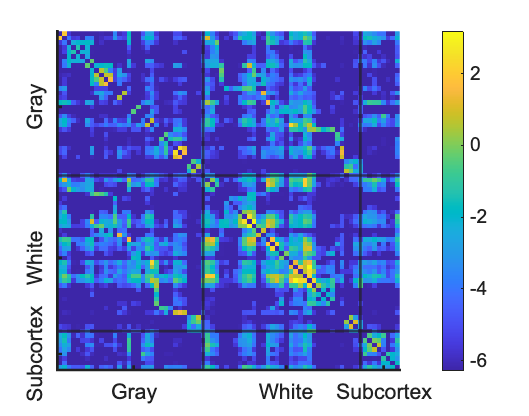

% Visualization fiber connectivity matrix
fiberPath = fullfile('step2_fiberTrack', 'DSI');
fiberName = [subID, '_ses-001_run-001_space-ACPC_desc-preproc_dwi.tt.gz.', ...
    subID, '_space-ACPC_roi.ncount.pass.connectivity.mat'];
load(fullfile(fiberPath, subID, fiberName), 'connectivity');
fiberCount = zeros(length(IEDlabels), length(IEDlabels));
for nChan1 = 1:length(IEDlabels)
    for nChan2 = 1:length(IEDlabels)
        Lia1 = ismember(contAnat.label, IEDlabels{nChan1});
        Lia2 = ismember(contAnat.label, IEDlabels{nChan2});
        fiberCount(nChan1, nChan2) = connectivity(Lia1, Lia2);
    end
end
fiberCount = log(fiberCount);
figure('Units', 'centimeters', 'Position', [5, 5, 14, 11]);
imagesc(fiberCount);
xline(cortexIdxMax, 'LineWidth', 2); yline(cortexIdxMax, 'LineWidth', 2);
xline(whiteIdxMax, 'LineWidth', 2); yline(whiteIdxMax, 'LineWidth', 2);
xticks([cortexIdxMean, whiteIdxMean, subcortexIdxMean]);
yticks([cortexIdxMean, whiteIdxMean, subcortexIdxMean]);
xticklabels({'Gray', 'White', 'Subcortex'});
yticklabels({'Gray', 'White', 'Subcortex'}); 
colorbar; colormap parula;
set(gca, 'box', 'off', 'FontName', 'Arial', ...
    'FontSize', 16, 'LineWidth', 2, 'YTickLabelRotation', 90);